srcDir = "..\srcImages\";

barbara = readraw(srcDir + "barbara.raw");

    "→Retrieving Image "    "..\srcImages\barbara.raw"    " ..."



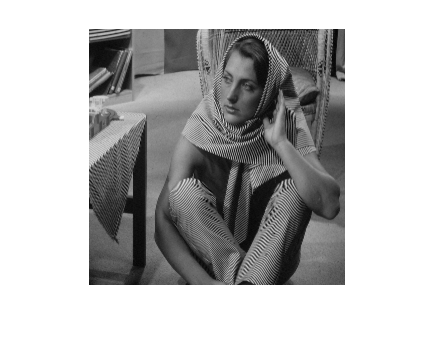

imshow(barbara);

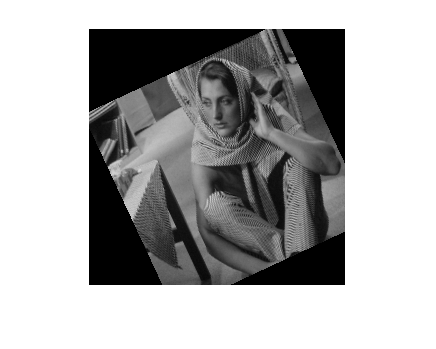


affectedBarbara = applyGeometryEffect(barbara, 3, 5, 2, 5);
imshow(affectedBarbara);

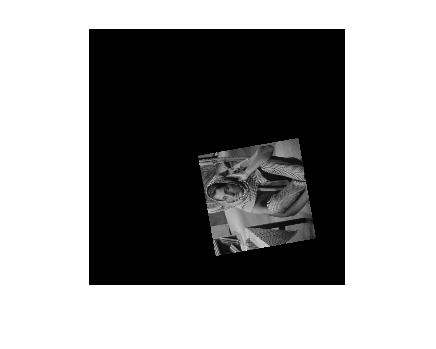


affectedBarbara = applyGeometryEffect(barbara, 3, 5, 2, 20);
imshow(affectedBarbara);

baboon = readraw(srcDir + "baboon.raw");

    "→Retrieving Image "    "..\srcImages\baboon.raw"    " ..."



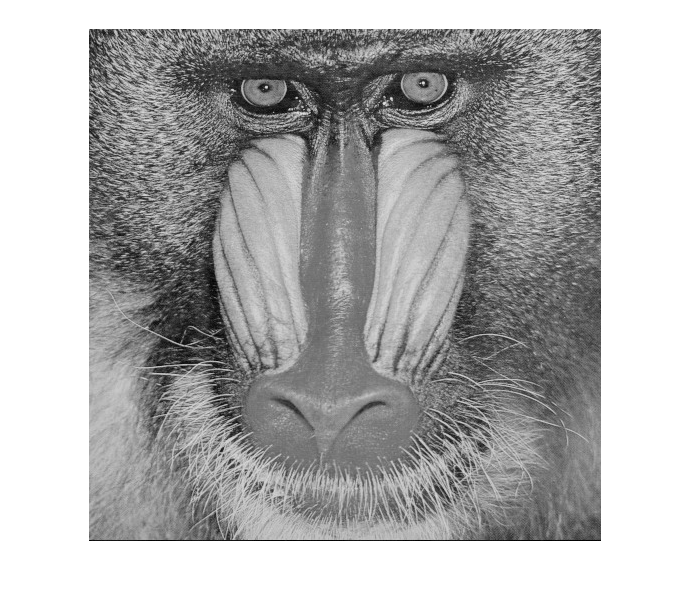

imshow(baboon);

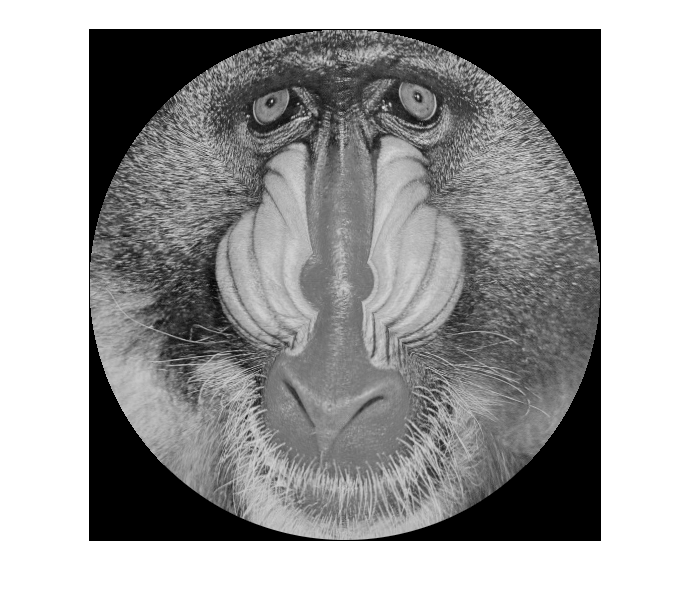


diskBaboon = toDisk(baboon);
imshow(diskBaboon);

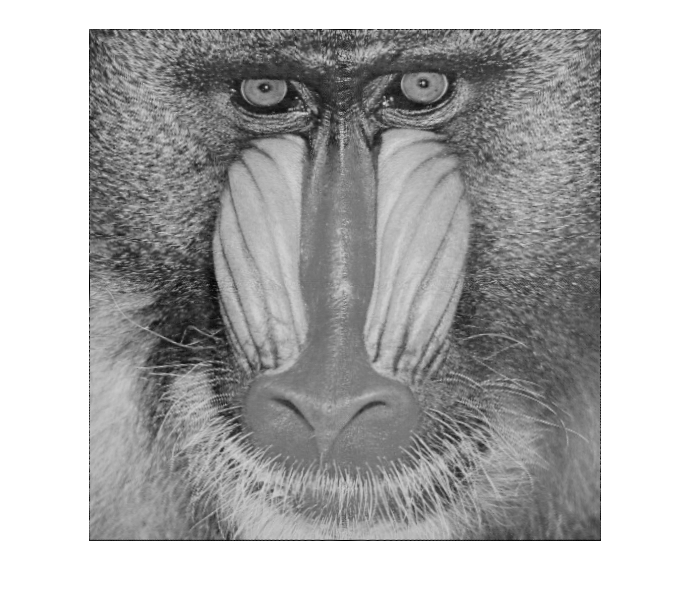


resquaredBaboon = fromDisk(diskBaboon);
imshow(resquaredBaboon);


%diskBaboon = warp(barbara, inverseDisk(128.5));
%imshow(diskBaboon);

%resquaredBaboon = fromDisk(baboon);
%imshow(resquaredBaboon);
%imshow(toDisk(resquaredBaboon));

txClasses = zeros(64, 64, 15);
for i = 1:15
    txClasses(:, :, i) = readraw(srcDir + "sample" + string(i) + ".raw");
end

    "→Retrieving Image "    "..\srcImages\sample1.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample2.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample3.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample4.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample5.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample6.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample7.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample8.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample9.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample10.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample11.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample12.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample13.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample14.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample15.raw"    " ..."




classes = classifyLawsSmallTextures(txClasses, 5);

mosaic1 = readraw(srcDir + "comb1.raw");

    "→Retrieving Image "    "..\srcImages\comb1.raw"    " ..."



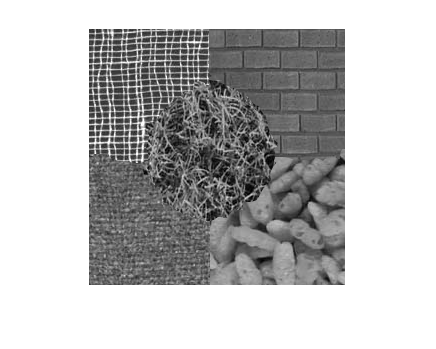

imshow(mosaic1);

clustered = clusterTextures(mosaic1, [0, 63, 127, 191, 255]);

cluster error is 1273398.5414
cluster error is 1273398.5401
cluster error is 1026597.9151
cluster error is 1026597.9064
cluster error is 1026597.9123


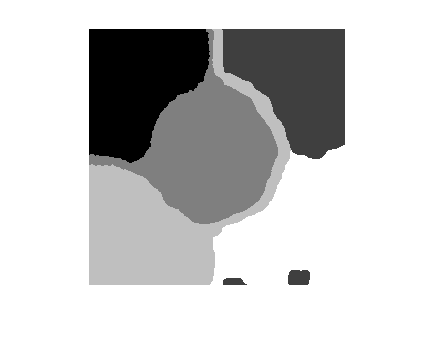

imshow(clustered);

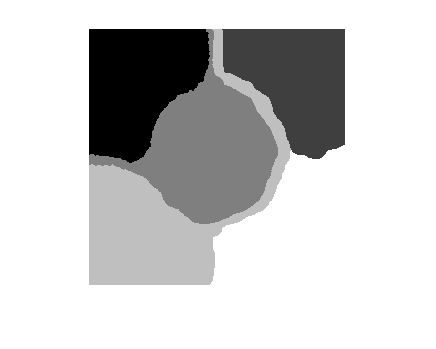

segmented = segmentClusters(clustered, [0, 63, 127, 191, 255]);
imshow(segmented);

mosaic2 = readraw(srcDir + "comb2.raw");

    "→Retrieving Image "    "..\srcImages\comb2.raw"    " ..."



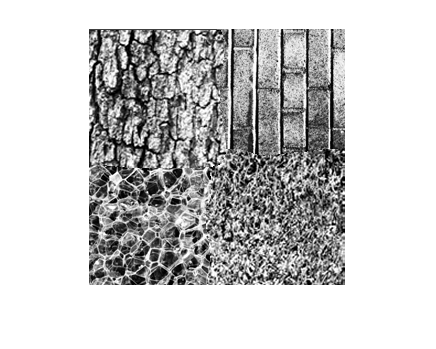

imshow(mosaic2);

clustered = clusterTextures(mosaic2, [0, 85, 170, 255]);

cluster error is 1818853.9095
cluster error is 1818853.864
cluster error is 1818853.9009
cluster error is 2268463.5989
cluster error is 1818854.0238


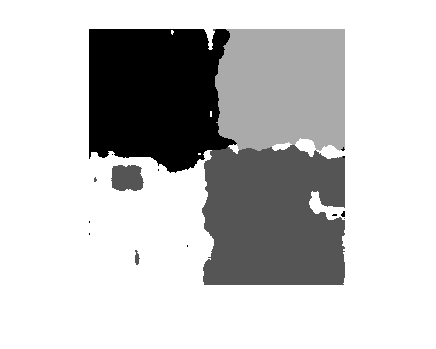

imshow(clustered);

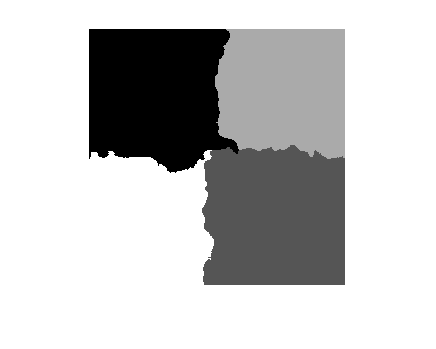

segmented = segmentClusters(clustered, [0, 85, 170, 255]);
imshow(segmented);

%colors = [0, 85, 170, 255];
%connectedParts = connectedComponents(segmented2);
%frequencyList = frequencies(connectedParts);
%keptComponents = largestComponents(segmented2, connectedParts, [0, 85, 170, 255], frequencyList);
%segmented = mergeComponents(connectedParts, frequencyList, keptComponents);
%[rows, cols] = size(connectedParts);
%for row = 1:rows
%    for col = 1:cols
%        for i = 1:4
%            if segmented(row, col) == keptComponents(i)
%                segmented(row, col) = colors(i);
%            end
%        end
%    end
%end
%imshow(uint8(segmented));

training = toGrayScale(readraw_color(srcDir + "training.raw"));

    "→Retrieving Image "    "..\srcImages\training.raw"    " ..."



test1 = toGrayScale(readraw_color(srcDir + "test1.raw"));

    "→Retrieving Image "    "..\srcImages\test1.raw"    " ..."



test2 = readraw(srcDir + "test2.raw");

    "→Retrieving Image "    "..\srcImages\test2.raw"    " ..."



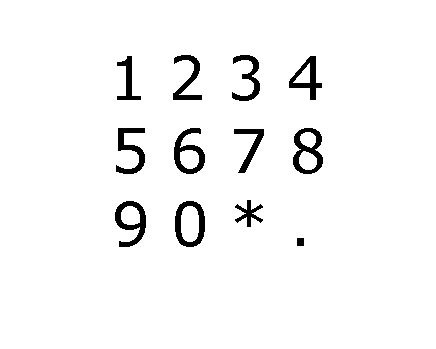

imshow(training);

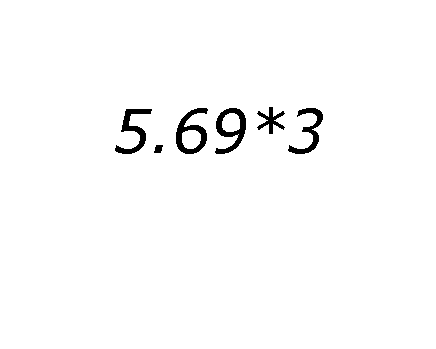

imshow(test1);

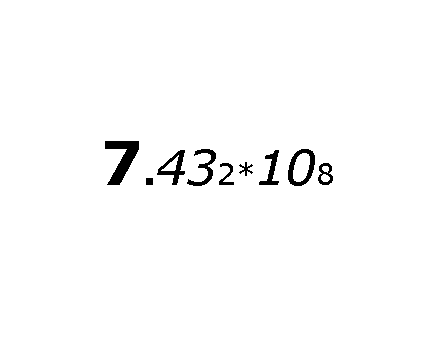

imshow(test2);

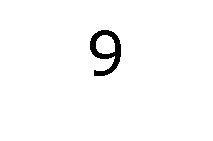

    48    33



ans =   OcrFeatures with properties:

                area: 608
           perimeter: 280
            eulerNum: 0
         circularity: 0.0975
    centralMomentRow: 2.2474
    centralMomentCol: -1.6730
           symmetryX: 0.5691
           symmetryY: 0.8553
         aspectRatio: 1.4545
    convexDeficiency: 1.1102


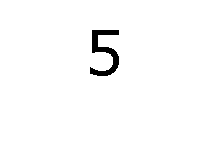

    48    31



ans =   OcrFeatures with properties:

                area: 564
           perimeter: 244
            eulerNum: 1
         circularity: 0.1190
    centralMomentRow: 1.4967
    centralMomentCol: 0.2949
           symmetryX: 0.9043
           symmetryY: 1.1277
         aspectRatio: 1.5484
    convexDeficiency: 1.6383


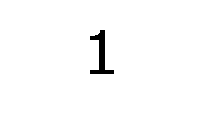

    46    26



ans =   OcrFeatures with properties:

                area: 374
           perimeter: 154
            eulerNum: 1
         circularity: 0.1982
    centralMomentRow: -0.8492
    centralMomentCol: -0.2226
           symmetryX: 0.2353
           symmetryY: 0.6203
         aspectRatio: 1.7692
    convexDeficiency: 2.1979


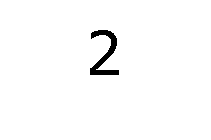

    47    31



ans =   OcrFeatures with properties:

                area: 492
           perimeter: 238
            eulerNum: 1
         circularity: 0.1091
    centralMomentRow: -2.3149
    centralMomentCol: -1.3340
           symmetryX: 0.9390
           symmetryY: 1.0203
         aspectRatio: 1.5161
    convexDeficiency: 1.9614


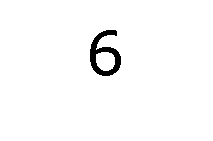

    48    33



ans =   OcrFeatures with properties:

                area: 609
           perimeter: 280
            eulerNum: 0
         circularity: 0.0976
    centralMomentRow: -2.1796
    centralMomentCol: 1.8106
           symmetryX: 0.5714
           symmetryY: 0.8506
         aspectRatio: 1.4545
    convexDeficiency: 1.1067


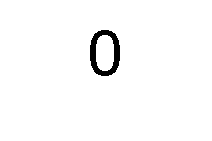

    48    32



ans =   OcrFeatures with properties:

                area: 601
           perimeter: 260
            eulerNum: 0
         circularity: 0.1117
    centralMomentRow: -0.0286
    centralMomentCol: 0.0564
           symmetryX: 0.0033
           symmetryY: 0.0033
         aspectRatio: 1.5000
    convexDeficiency: 0.6173


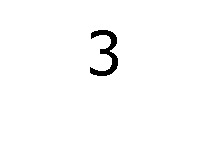

    48    30



ans =   OcrFeatures with properties:

                area: 487
           perimeter: 242
            eulerNum: 1
         circularity: 0.1045
    centralMomentRow: 0.0709
    centralMomentCol: -4.2672
           symmetryX: 0.9979
           symmetryY: 0.4230
         aspectRatio: 1.6000
    convexDeficiency: 1.9569


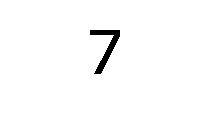

    46    32



ans =   OcrFeatures with properties:

                area: 410
           perimeter: 188
            eulerNum: 1
         circularity: 0.1458
    centralMomentRow: 5.1493
    centralMomentCol: -0.7521
           symmetryX: 1.0634
           symmetryY: 1.4537
         aspectRatio: 1.4375
    convexDeficiency: 2.5902


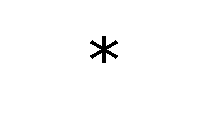

    29    30



ans =   OcrFeatures with properties:

                area: 290
           perimeter: 202
            eulerNum: 1
         circularity: 0.0893
    centralMomentRow: 0
    centralMomentCol: 0
           symmetryX: 0
           symmetryY: 0
         aspectRatio: 1.0345
    convexDeficiency: 2



hullBounds = convexHullsFor(training);
[hulls, ~] = size(hullBounds);
for i = 1:9
    figure;
    convexHull = binaryImgForBounds(training, hullBounds(i, :));
    imshow(fromBinary(convexHull));
    ocrFeaturesForHull(convexHull)
end


%hullBounds = convexHullsFor(test1);
%[hulls, ~] = size(hullBounds);
%for i = 1:hulls
%    figure;
%    convexHull = binaryImgForBounds(test1, hullBounds(i, :));
%    imshow(fromBinary(convexHull));
%    ocrFeaturesForHull(convexHull)
%end

%hullBounds = convexHullsFor(test2);
%[hulls, ~] = size(hullBounds);
%for i = 1:hulls
%    figure;
%    convexHull = binaryImgForBounds(test2, hullBounds(i, :));
%    imshow(fromBinary(convexHull));
%    ocrFeaturesForHull(convexHull)
%end

training = toGrayScale(readraw_color(srcDir + "training.raw"));

    "→Retrieving Image "    "..\srcImages\training.raw"    " ..."



test1 = toGrayScale(readraw_color(srcDir + "test1.raw"));

    "→Retrieving Image "    "..\srcImages\test1.raw"    " ..."



test2 = readraw(srcDir + "test2.raw");

    "→Retrieving Image "    "..\srcImages\test2.raw"    " ..."




imshow(test1);

charClasses = buildOcrClasses(training);
classified = ocrSegmentAndClassify(test1, charClasses);

    47    39

    10    11

    48    34

    48    33

    29    30

    48    37



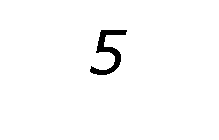

five


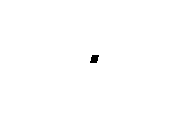

dot


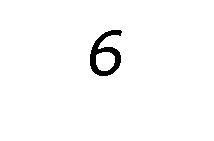

six


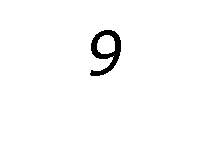

nine


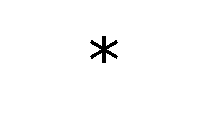

star


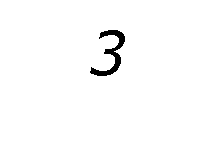

three


[~, toShow] = size(classified);
for i = 1:toShow
    figure;
    imshow(fromBinary(classified(i).convexHull));
    disp(classified(i).textName);
end


imshow(test2);

classified = ocrSegmentAndClassify(test2, charClasses);

    46    36

     9     9

    37    30

    39    31

    24    17

    16    16

    37    22

    39    29

    24    17



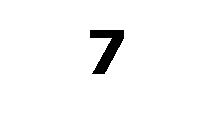

seven


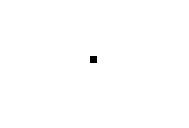

dot


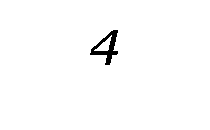

four


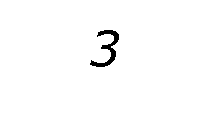

three


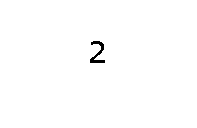

two


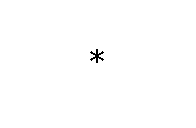

star


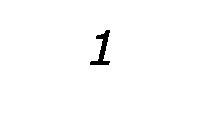

one


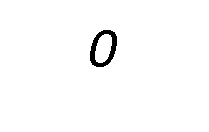

zero


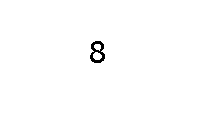

eight


[~, toShow] = size(classified);
for i = 1:toShow
    figure;
    imshow(fromBinary(classified(i).convexHull));
    disp(classified(i).textName);
end

cwru = fixedThreshold(toGrayScale(readraw_color(srcDir + "cwru.raw")), 127);

    "→Retrieving Image "    "..\srcImages\cwru.raw"    " ..."



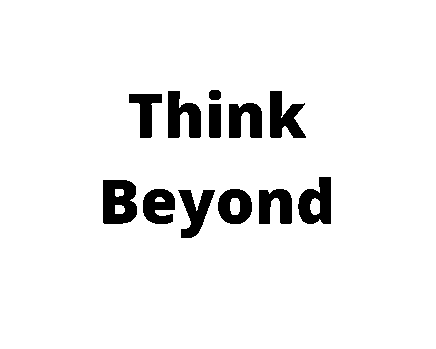

figure;
imshow(cwru);

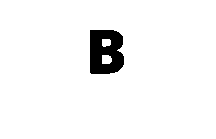

eight


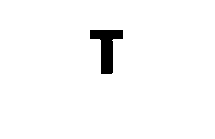

seven


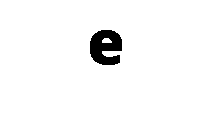

zero


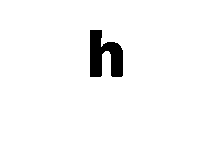

one


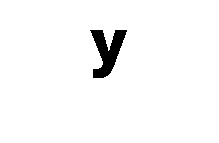

one


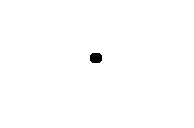

dot


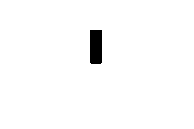

dot


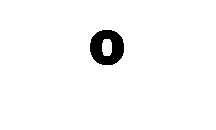

zero


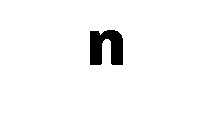

one


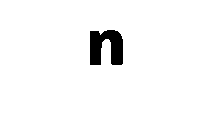

one


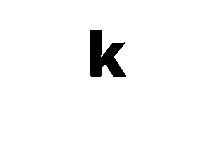

one


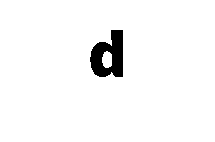

zero



charClasses = buildOcrClasses(training);
classified = ocrSegmentAndClassify(cwru, charClasses);
[~, toShow] = size(classified);
for i = 1:toShow
    figure;
    imshow(fromBinary(classified(i).convexHull));
    disp(classified(i).textName);
end